Plots the points of a quadrature rule$~$

### Syntax                                                                                                                                                                                                                                                                                                                                                                                                                                                                     

quadplot(Q)


$$~$$


### Description                                                                                                                                                                                                                                                                                                                                                                                                                                                                  

`quadplot``(Q) `plots the points of quadrature rule `Q`, which is a structure with fields` Q.Points, Q.Weights `and` Q.Properties, `over the domain of integration defined within `Q.Properties. `(Note: For two-dimensional rules, points that are outside the domain and/or have corresponding negative weights are indicated by red, see Example 2 below).

`quadplot``(Q,Name,Value) `same as above but with additional plot options provided by using any of the following `Name-Value` pairs:

`'PlotTitle'` — Controls plot title 

`'on'` (default) │` 'off'`

Turns `'on'` (default) or `'off'` the plot title. The default title plot includes the number of points, the type, and degree of the quadrature rule.

`'PointLabels'` — Controls point labels

`'off'` (default) │` 'on'`

Turns `'off'` (default) or `'on'` point labels that indicate the index of the point in `Q.Points`, i.e., coordinate(s) of the point labeled `i` are `Q.Points(i,:)`. 

### Examples                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

**Example 1 **$-$**  Plots of a one-dimensional quadrature rule**

The `quadplot` function provides a simple way to visualize the distribution of points and properties of a given quadrature rule. For example, suppose an 8-point Gauss–Lobatto rule is obtained via

Q = quadGaussLobatto(8);

This can be easily visualized using the `quadplot` function, where it can be noted that the plot title displays the number of points, type and degree of the quadrature rule.

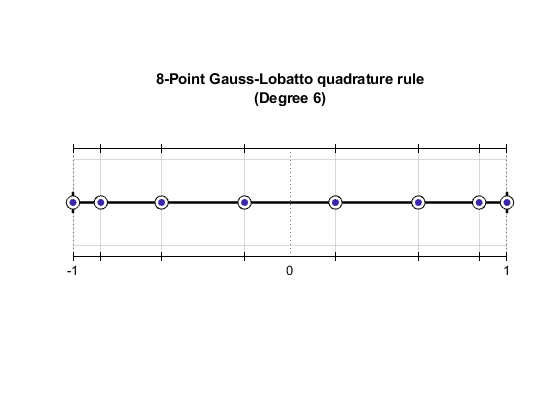

quadplot(Q)

The plot title can be turned off and the point labels can be turned on by specifying the following `Name-Value` pairs:

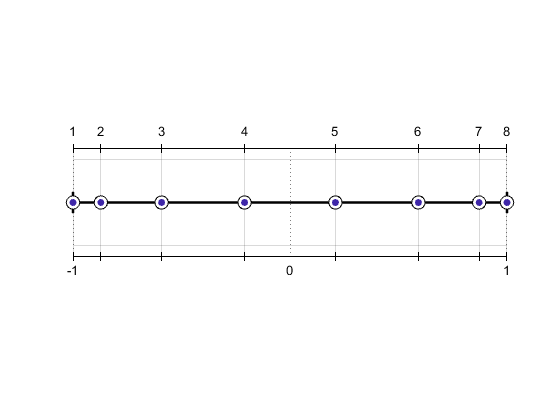

figure; quadplot(Q,'PlotTitle','off','PointLabels','on')

where it can be observed that the quadrature points are stored in ascending order in `Q.Points.`

**Example 2 **$-$**  Plots of two-dimensional quadrature rules**

The `quadplot` function can also be used to visualize the two-dimensional quadrature rules for the square and triangle. For example,  a degree 7 (Gauss–Legendre product) quadrature rule for the square can be obtained by

QLegendre = quadsquare(7);

and plotted using the `quadplot` function

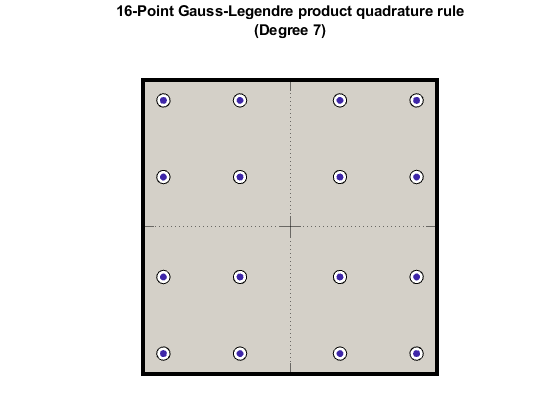

figure; quadplot(QLegendre);

Another option for a degree 7 product rule on the square is a Gauss–Lobatto product rule ontained by specifying following `Name-Value` pair:

QLobatto = quadsquare(7,'Type','productLobatto');

and again plotted using the `quadplot` function.

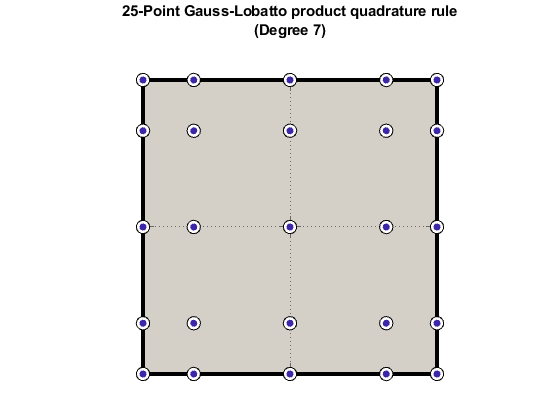

figure; quadplot(QLobatto);

Note that although the latter quadrature rule uses a greater number of points, it may be preferred in situations where both edge and area integrals over the square need to be computed. 

Finally, as an example of plotting a nonproduct quadrature rule, consider the degree 3 nonproduct quadrature rule for the triangle where we allow the presence of negative weights, i.e.,

Qt = quadtriangle(3,'Type','nonproduct','Weights','allowNegative');

which can be plotted (turning point labels on) using the `quadplot` function

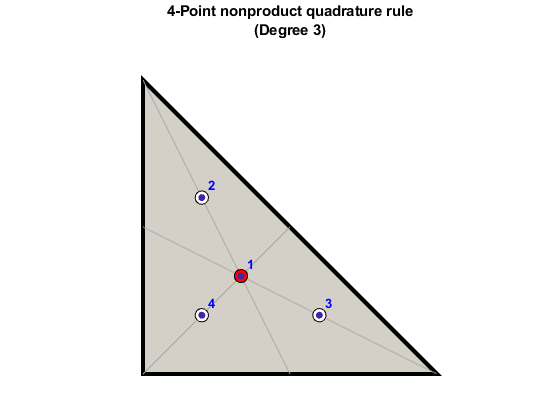

figure; quadplot(Qt,'PointLabels','on')

Note in this case one of the quadrature points is negative, which appears in red. Positive weights are generaly preferred among finite element practioners.

#### *This function is part of........*